Handle = initializeAndor();


******Start initialization******

Camera (serial: 19330, handle: 100) is set to current CCD
Camera (serial: 19331, handle: 201) is set to current CCD


setCurrentAndor(19331, Handle)

Camera (serial: 19331, handle: 201) is set to current CCD


setModeFK(exposure=0.2, num_frames=8, external_trigger=false)


******Fast Kinetic mode******

Current camera serial number: 19331
Number of frames: 8
Exposure time: 0.200s
Kinetic cycle time: 0.201s
Trigger: Internal



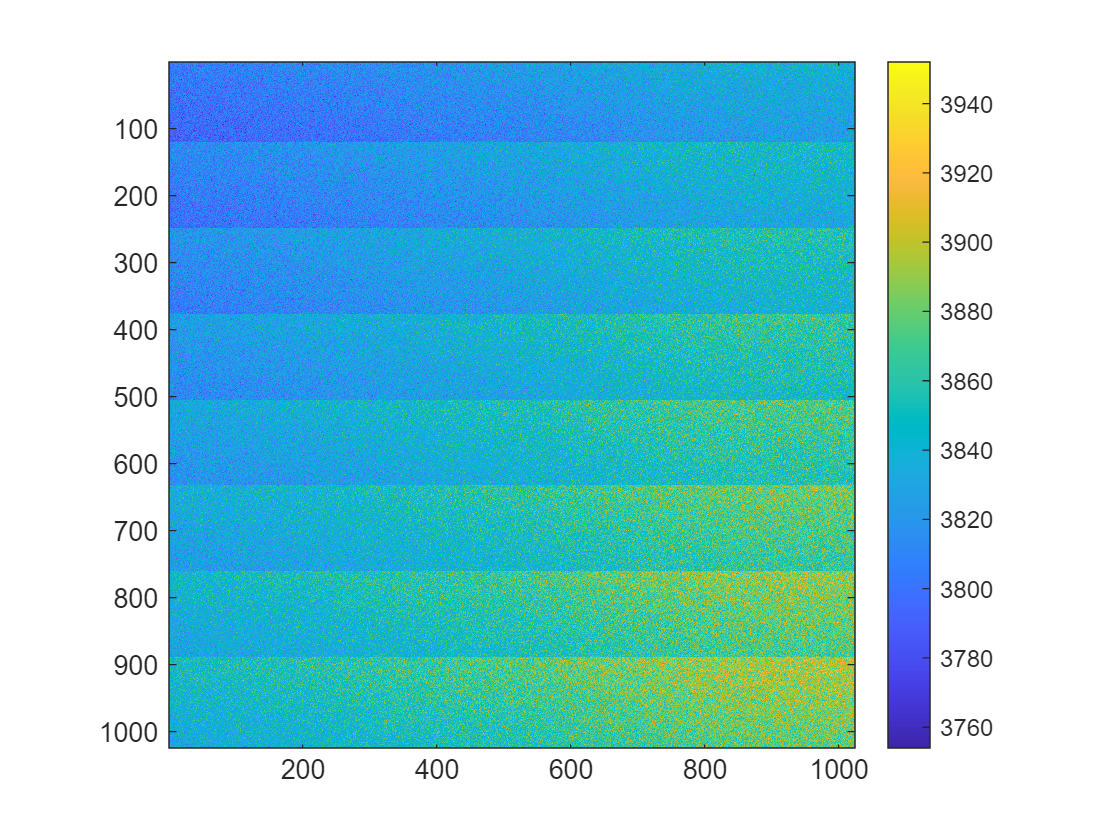

[ret, XPixels, YPixels] = GetDetector();
CheckWarning(ret)

sample = acquireAndorImage();

figure
imagesc(sample)
daspect([1 1 1])
colorbar

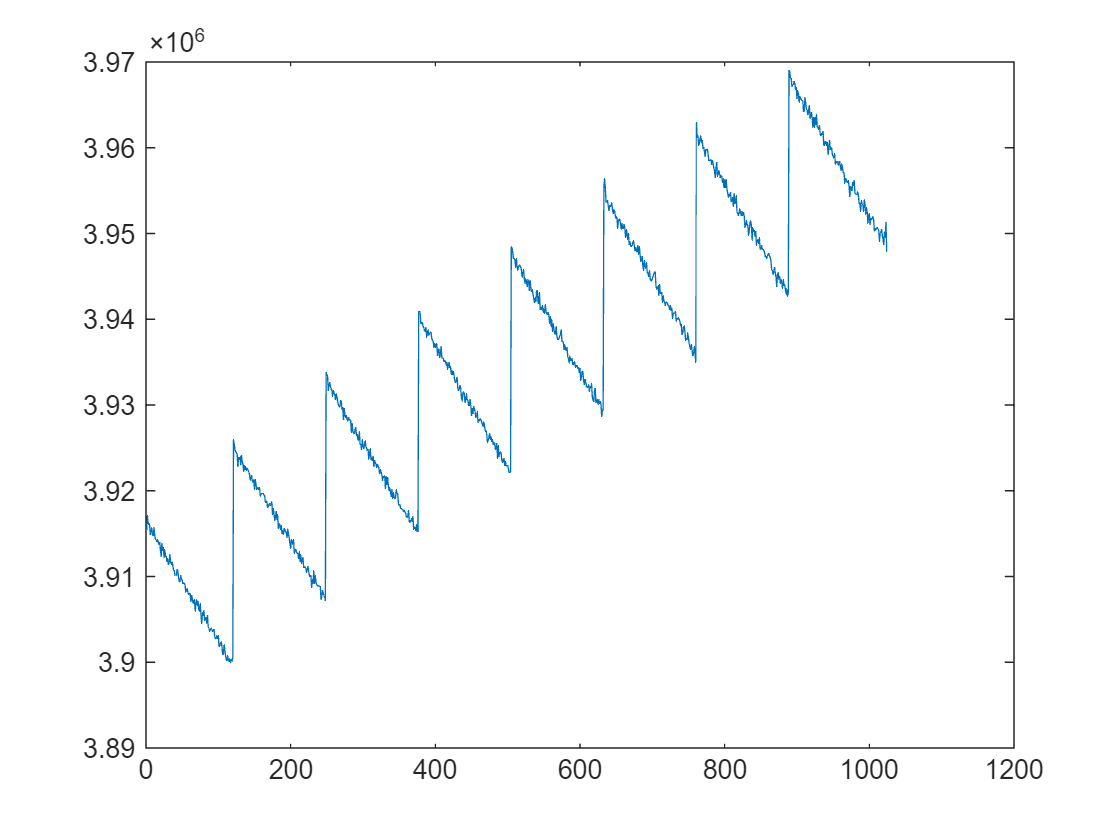

y_sum = sum(sample, 2);

figure
plot(y_sum)